## Analysis Pipeline for PEP WP-4 EEG Project

### House keeping

clc; clear; close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))

### Define to-be-analyzed subjects

%cfg.subNums = [101:103, 105:106, 108:117, 119:122, 124, 126:130, 133]; % 118 did not finish the experiment, 140, 114
cfg.subNums = [101:106, 108:117, 119:122, 124, 126:131, 133, 141:142];
cfg = defaultCfg(cfg);

### Preprocessing

disp(['Running pre-processing...' newline]);

Running pre-processing...



preprocess_EEG(cfg);

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

### Category decoding

disp(['Running decoding...' newline]);
%decoding_EEG(cfg);

### Individual decoding accuracies

disp(['Running individual decoding...' newline]);
%individual_decoding_accuracies(cfg);

### Pairwise decoding

cfg.plotting = false;
disp(['Running pairwise decoding...' newline]);

Running pairwise decoding...



[d.pairRep, d.meanAcc, cfg] = PairwiseTPLDAclassifier(cfg);

RDM for sub-101 already exists
RDM for sub-102 already exists
RDM for sub-103 already exists
RDM for sub-105 already exists
RDM for sub-106 already exists
RDM for sub-108 already exists
RDM for sub-109 already exists
RDM for sub-110 already exists
RDM for sub-111 already exists
RDM for sub-112 already exists
RDM for sub-113 already exists
RDM for sub-114 already exists
RDM for sub-115 already exists
RDM for sub-116 already exists
RDM for sub-117 already exists
RDM for sub-119 already exists
RDM for sub-120 already exists
RDM for sub-121 already exists
RDM for sub-122 already exists
RDM for sub-124 already exists
RDM for sub-126 already exists
RDM for sub-127 already exists
RDM for sub-128 already exists
RDM for sub-129 already exists
RDM for sub-130 already exists
RDM for sub-133 already exists


### **t-test**

cfg.plotting = true;
disp(['Running t-test on pairwise decoding accuracies...' newline]);

Running t-test on pairwise decoding accuracies...



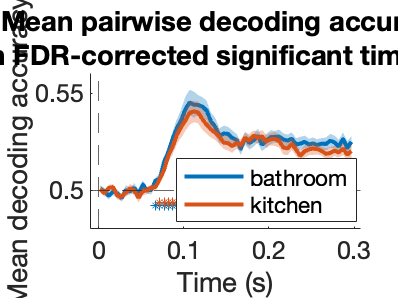

stats_ttest(cfg, d);

### ISC of representation

cfg.plotting = true;
cfg.regressOutMean = false;
disp(['Running ISC...' newline]);

Running ISC...



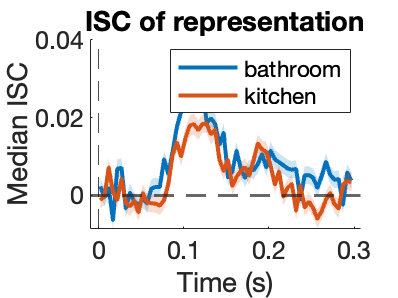

d = getISCofRespresentation(cfg, d);

### ISC of representation with regressOutMean

cfg.regressOutMean = true;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep'};
cfg.correlation_type = 'spearman';
cfg.plotting = true;
cfg.new_figure = false;
disp(['Running ISC...' newline]);

Running ISC...



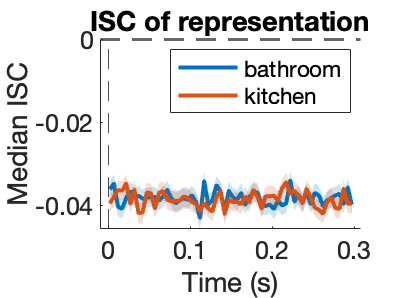

d = getISCofRespresentation(cfg, d);

### Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
%cfg.layer_type = 'early_mid';
cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;
cfg.plot_rdm = false;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

% get images
cfg.analysis_names = {'typical', 'control','photos'};
images = load_images(cfg);

Loaded image: 101_bat_gen1.png
Loaded image: 101_bat_gen2.png
Loaded image: 101_bat_gen3.png
Loaded image: 102_bat_gen1.png
Loaded image: 102_bat_gen2.png
Loaded image: 102_bat_gen3.png
Loaded image: 103_bat_gen1.png
Loaded image: 103_bat_gen2.png
Loaded image: 103_bat_gen3.png
Loaded image: 104_bat_gen1.png
Loaded image: 104_bat_gen2.png
Loaded image: 104_bat_gen3.png
Loaded image: 105_bat_gen1.png
Loaded image: 105_bat_gen2.png
Loaded image: 105_bat_gen3.png
Loaded image: 106_bat_gen1.png
Loaded image: 106_bat_gen2.png
Loaded image: 106_bat_gen3.png
Loaded image: 107_bat_gen1.png
Loaded image: 107_bat_gen2.png
Loaded image: 107_bat_gen3.png
Loaded image: 108_bat_gen1.png
Loaded image: 108_bat_gen2.png
Loaded image: 108_bat_gen3.png
Loaded image: 109_bat_gen1.png
Loaded image: 109_bat_gen2.png
Loaded image: 109_bat_gen3.png
Loaded image: 110_bat_gen1.png
Loaded image: 110_bat_gen2.png
Loaded image: 110_bat_gen3.png
Loaded image: 111_bat_gen1.png
Loaded image: 111_bat_gen2.png
Loaded i

% layer similiarity
[d, cfg] = get_dnn_layer_similarity(d, images, cfg); % in the function cfg.regressOutMean = false!

analysis typical - layer #1 - category: bathroom
analysis control - layer #1 - category: bathroom
analysis photos - layer #1 - category: bathroom
analysis typical - layer #1 - category: kitchen
analysis control - layer #1 - category: kitchen
analysis photos - layer #1 - category: kitchen


% filter for included subjects
%d = filterCurrentSubs(d, cfg);

### Compare ISC from drawings with ISC of neural representations 

 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated


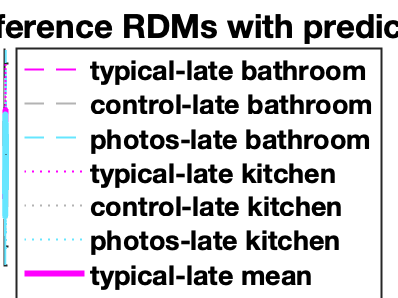

% preparation
cfg.partial_cor = true;
cfg.plotting = true;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
% cfg.predictor_RDMs = {'typical_early', 'control_early', 'photos_early'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.dnns = {'vgg16_imagenet'};
cfg.show_single_cate = true;
cfg.partial_correlation_type = 'pearson';

% run
d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

### Permutation test

cfg.n_permutations = 5000;
cfg.alpha = 0.05;
d = stats_permutationtest(cfg,d);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluat

plot_corr_sig(cfg,d,d.pvalMat_onesided);

### Behavioral data

Out of 2 tests, 2 are significant using a false discovery rate of 0.050000.
FDR/FCR procedure used is guaranteed valid for independent or positively dependent tests.
Out of 26 tests, 26 are significant using a false discovery rate of 0.050000.
FDR/FCR procedure used is guaranteed valid for independent or positively dependent tests.
All  subjects are significant better then chance level.


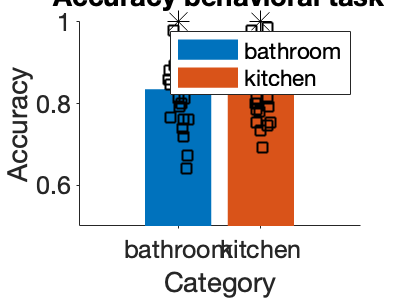

d.beh = beh_task(cfg);

### Stimuli RDM

cfg.dnns = {'vgg16_imagenet'};
% cfg.layer_type = 'late';
cfg.layer_type = 'early_mid_late';
cfg.correlation_type = 'Spearman';
cfg.plot_rdm = true;
cfg.new_figure = true;
cfg.analysis_names = {'stimuli'};
cfg.exp_num = 2;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features', 'stimuli');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

if ~exist('images','var')
    images = struct;
end

Loaded image: labelme_sfxiulhjbhlyiyt.tif
Loaded image: sun_aapitsgbtktqubfy.tif
Loaded image: sun_aavhrsfjbserjtht.tif
Loaded image: sun_abapwbhyhkfixyex.tif
Loaded image: sun_abjtwfukuwddzted.tif
Loaded image: sun_acduarbnmmoglmiv.tif
Loaded image: sun_acegryoqftbzowsg.tif
Loaded image: sun_acgyywnybuveqsro.tif
Loaded image: sun_aclfzgynxzxlbepz.tif
Loaded image: sun_afcoljnjfoxjtgja.tif
Loaded image: sun_aggnnqpdorgxpvce.tif
Loaded image: sun_agguqiubmwhqqunb.tif
Loaded image: sun_aghyqhbptboemmoq.tif
Loaded image: sun_agrwbmhcpmfuwmsg.tif
Loaded image: sun_agyqfjcfkdcydepw.tif
Loaded image: sun_ahaulkltgpkeeemi.tif
Loaded image: sun_ahcvzmoyaycdoftf.tif
Loaded image: sun_ahijqszoswveeyji.tif
Loaded image: sun_ahqjwnzgolcaoidx.tif
Loaded image: sun_ajlawzvmubibwbpy.tif
Loaded image: sun_akiytfaagpdsphgz.tif
Loaded image: sun_aleqenyvunhactkl.tif
Loaded image: sun_aljolscmmzydegqp.tif
Loaded image: sun_alkosphxlxwjwgjd.tif
Loaded image: sun_alotolagknyrgtsk.tif
Loaded image: sun_ambr

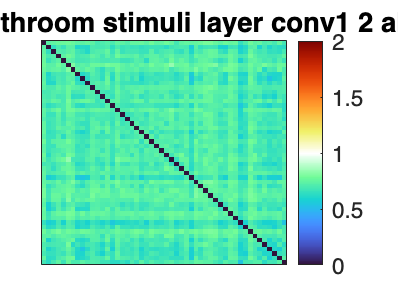

analysis stimuli - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


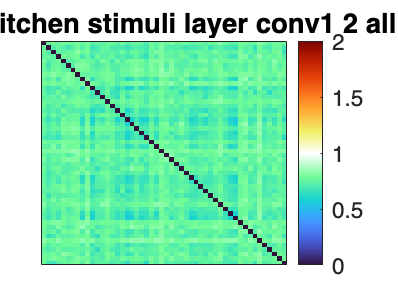

analysis stimuli - layer #2 - category: bathroom
Length of labels do not match matrix dimensions


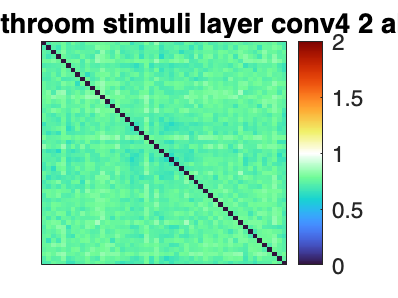

analysis stimuli - layer #2 - category: kitchen
Length of labels do not match matrix dimensions


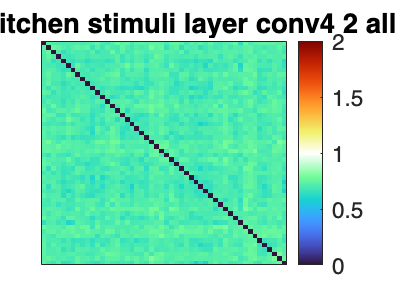

analysis stimuli - layer #3 - category: bathroom
Length of labels do not match matrix dimensions


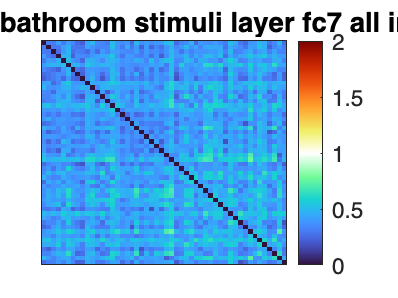

analysis stimuli - layer #3 - category: kitchen
Length of labels do not match matrix dimensions


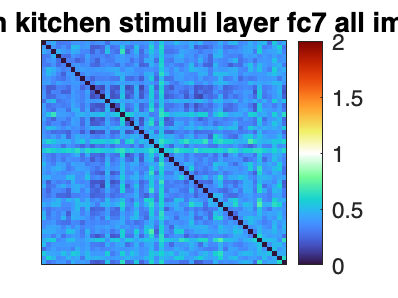

% cfg.layer_names = {'early', 'mid', 'late'};
cfg.predictor_RDMs = {'stimuli_early', 'stimuli_mid', 'stimuli_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
[cfg, d, images] = make_RDM_for_stimuli(cfg, d, images);

Stimuli

cfg.save_name = 'compare_tp_RDMs_to_stimuli_RDM'

cfg = struct with fields:
                functionPath: '/Users/theaschmitt/Documents/Data Science/6.Semester/Thesis/pep_wp4_eeg/code/utilities'
                     subNums: [101 102 103 105 106 108 109 110 111 112 113 114 115 116 117 119 120 121 122 124 126 127 128 129 130 133]
                           n: 26
                  categories: {'bathroom'  'kitchen'}
                     exp_num: 2
                     nTrials: 100
                     nBlocks: 20
                 trialLength: 0.2500
                   ISC_types: {'pairRep'}
                         dnn: 'vgg16_imagenet'
              analysis_names: {'stimuli'}
                    plotting: 1
                      saving: 1
               dissimilarity: 1
                  classifier: @cosmo_classify_lda
              sourcedataPath: '/Users/theaschmitt/Documents/Data Science/6.Semester/Thesis/pep_wp4_eeg/code/../sourcedata'
                  outputPath: '/Users/theaschmitt/Documents/Data Science/6.Semester/Thesis/pep_w

d.stimuli = compare_pairwiseDecodingRDM_with_stimuliRDM(cfg, d);

subject 101
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 102
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 103
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 105
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 106
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 108
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 109
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 110
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
P

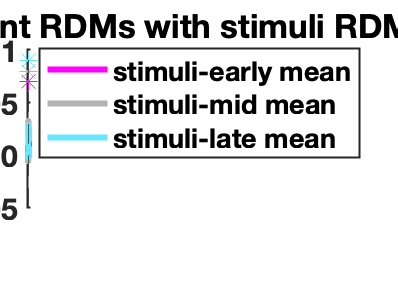

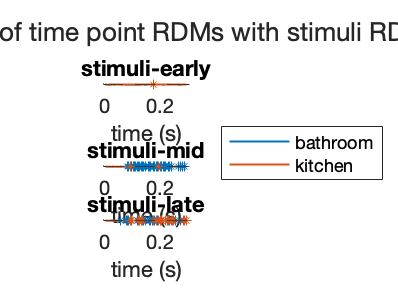

cfg.plotting = true;
cfg.alpha = 0.05;
stats_ttest_stimuli(cfg,d);

End Message

% finished!
disp([ ...
    newline, ...
    '#########################', ...
    newline, ...
    '####### ALL DONE! #######', ...
    newline, ...
    '#########################', ...
    newline ...
    ]);


#########################
####### ALL DONE! #######
#########################

